% loads data sets

s3_4kb = load('../dat/3_4kb_21_04_24/nucleus_struct.mat');
s2_65kb = load('../dat/2_65kb_21_04_24/nucleus_struct.mat');
s1_9kb = load('../dat/1_9kb_21_04_24/nucleus_struct.mat');


% Pick out a subset of data
nc = 14;
nucleus_struct = s3_4kb.nucleus_struct;

% can pick out a specific set within the data
%nucleus_struct = nucleus_struct([nucleus_struct.setID] == 3);

subset = nucleus_struct([nucleus_struct.ncStart] == nc);

Plot raw traces with error

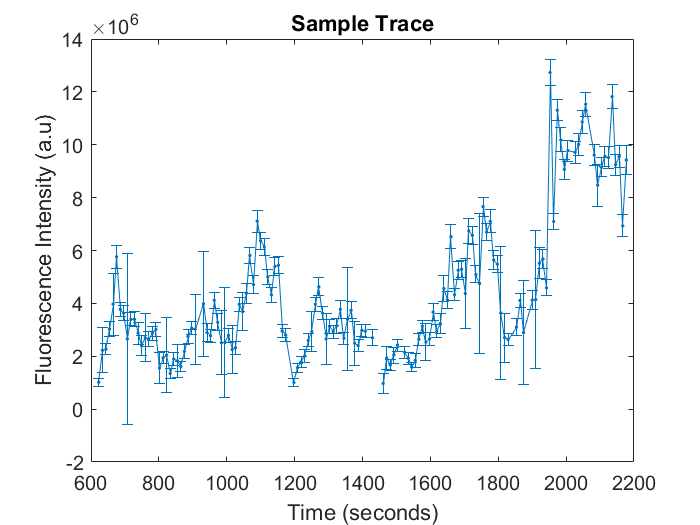

% plots raw trace with certain precondtions; no cleaning, no interpolation

% picks out traces that have decent number of fluorescence measurements
goods = subset([subset.ap_flag] == 1000);
j = 1;
for i = 1:length(subset)
    if sum(~isnan(subset(i).fluo3DN)) > 100
        goods(j) = subset(i);
        j = j + 1;
    end
end

i = 4;
figure()
times = goods(i).time;
fluo = goods(i).fluo3DN;
fluoSE = goods(i).fluo3DNSE;
errorbar(times, fluo, fluoSE, '.-');
xlabel('Time (seconds)');
ylabel('Fluorescence Intensity (a.u)');
title('Sample Trace');

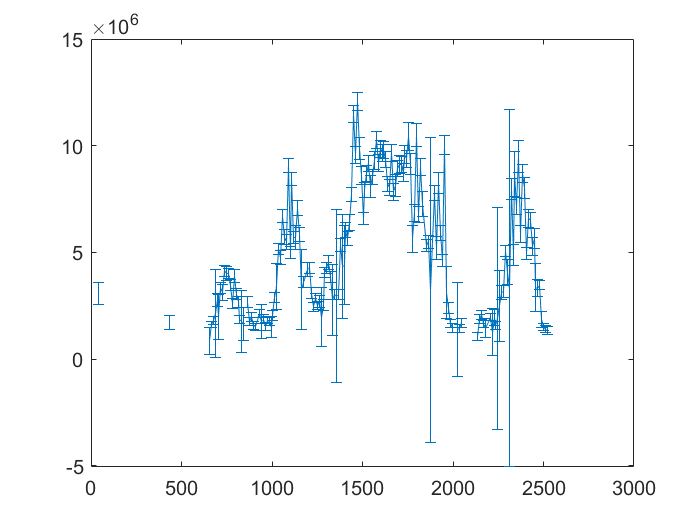

% show raw traces, no preconditions
i = 90;
figure();
errorbar(subset(i).time, subset(i).fluo3DN, subset(i).fluo3DNSE);

Plots histogram of xy plane distance travelled from frame to frame for nuclei

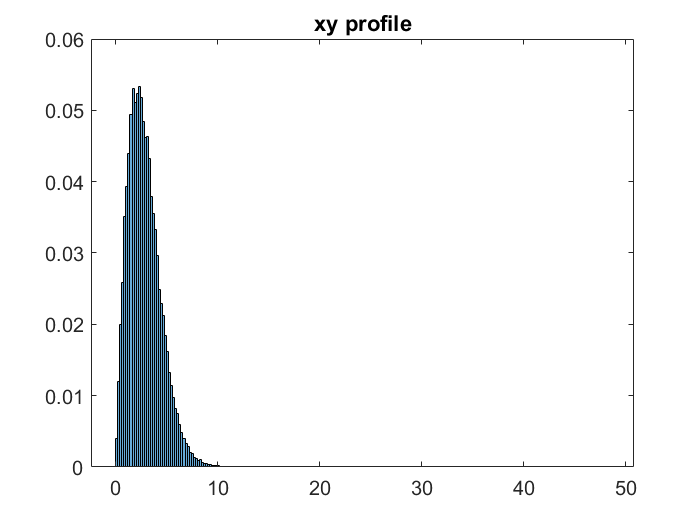


xy_moves = [];
max_xys = [];
for i = 1:length(subset)
    xposes = subset(i).xPosParticle;
    yposes = subset(i).yPosParticle;
    del_x = diff(xposes);
    del_y = diff(yposes);
    del_xy = sqrt(del_x.*del_x + del_y.*del_y);
    xy_moves = [xy_moves del_xy(~isnan(del_xy))];

    if sum(~isnan(del_xy)) > 0
        max_xys = [max_xys max(del_xy)];
    end
end

figure();
histogram(xy_moves, 'Normalization',"probability");
%set(gca, 'YScale', 'log')
title('xy profile');

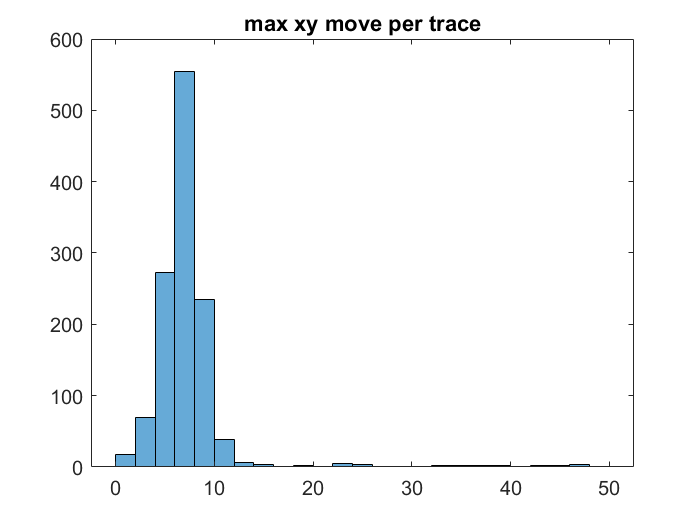



figure();
histogram(max_xys);
title('max xy move per trace');

Looks at range of fluo, change of fluo and change of change of fluo values

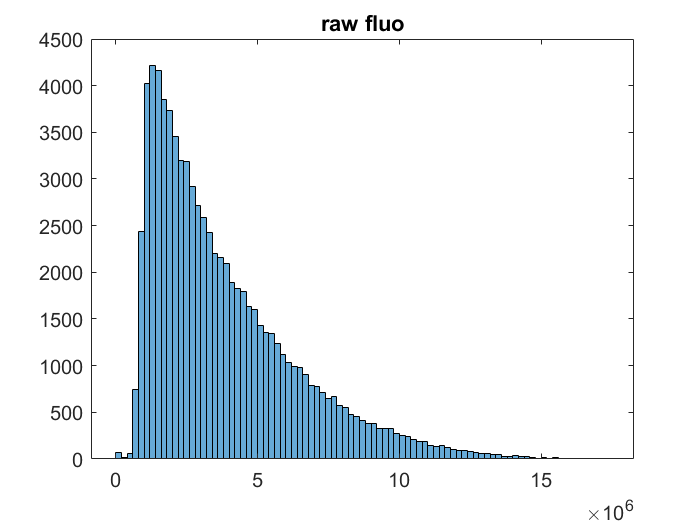

all_fluos = [];
all_dfluos = [];
all_ddfluos = [];
for i = 1:length(subset)
    fluo3DN = subset(i).fluo3DN;
    all_fluos = [all_fluos fluo3DN];
    all_dfluos = [all_dfluos diff(fluo3DN)];
    all_ddfluos = [all_ddfluos diff(diff(fluo3DN))];
end

figure();
histogram(all_fluos);
title('raw fluo')

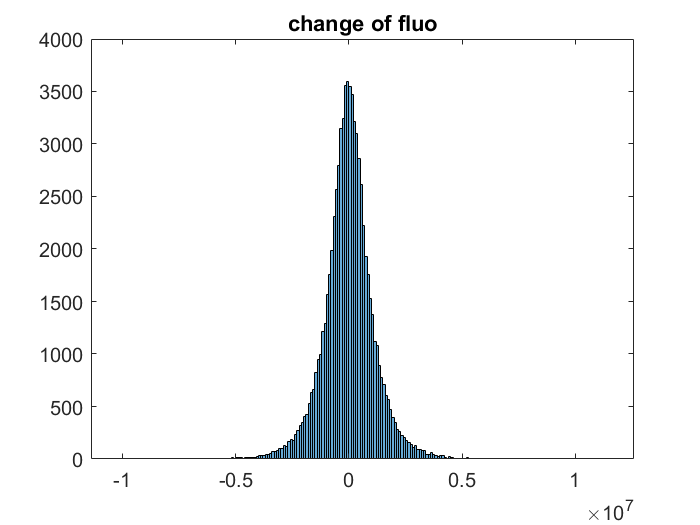


figure();
histogram(all_dfluos);
title('change of fluo')

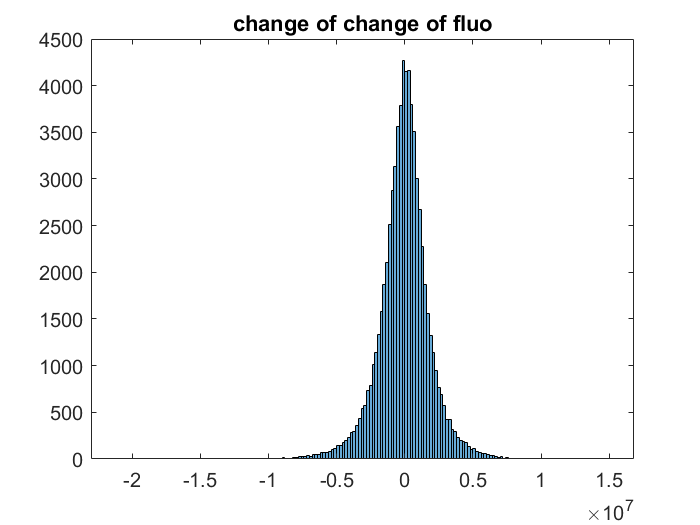


figure();
histogram(all_ddfluos);
title('change of change of fluo')

Processes traces from scratch

% clean parameters
min_valid = 40;
thresh = 0;
max_del_z = 2;
max_del_xy = 8;
f = 1.5;
cut = 0;
min_avg = 0;

% parametesr from traces
time_res = nanmedian(diff([subset.time]));
jump_thresh = prctile(diff(diff([subset.fluo3DN])), 99.5);
num_big = 0;

tracesp = {};
tracesp_alt = {};
tracesp_alt2 = {};
idx = 1;
idx_alt = 1;
idx_alt2 = 1;
num_pass = 0;
num_fail = 0;
for i = 1:length(subset)
    fluo = subset(i).fluo3DN;
    time = subset(i).time;
    xPos = subset(i).xPosParticle;
    yPos = subset(i).yPosParticle;
    
    % figures out timing for interpolation
    t_start = time(1);
    t_end = round((time(end) - t_start) ...
        / time_res) * time_res + t_start;
    time_interp = t_start:time_res:t_end;
    
    % nans too big movements
    del_xy = sqrt(diff(xPos).^2 + diff(yPos).^2);
    tr_del_xy = [0 max(del_xy(1:end-1), del_xy(2:end)) 0];
    fluo(tr_del_xy >= max_del_xy) = NaN;  
    
    tr_dd1 = abs([0 diff(diff(fluo)) 0]);
    %tr_dd1 = abs([0 diff(fluo) 0]);
    fluo(tr_dd1>jump_thresh) = NaN;
    num_big = num_big + length(find(tr_dd1 > jump_thresh));
    
    % interpolates
    non_nans = find(~isnan(fluo));
    if length(non_nans) < min_valid
        continue
    end
    trace = interp1(time(non_nans), ...
        fluo(non_nans), time_interp);
    
    % nans below thresh
    trace(trace < thresh) = NaN;
    
    % nans anything not close to known point
    new_times = time(non_nans);
    for j = 1:length(time_interp)
        higher = find(new_times > time_interp(j));
        lower = find(new_times < time_interp(j));
        if isempty(higher) || isempty(lower)
            continue
        end
        dist_high = new_times(higher(1)) - time_interp(j);
        dist_low = time_interp(j) - new_times(lower(end));
        if dist_low > f*time_res && dist_high > f*time_res
            trace(j) = NaN;
            num_fail = num_fail + 1;
            if ~(dist_low > f*time_res && dist_high > f*time_res)
                stop = true;
            end
        else
            num_pass = num_pass + 1;
        end
    end
    
    % divide into segments
    bad_pts = [1 find(isnan(trace)) length(trace)];
    for j = 2:length(bad_pts)
        if bad_pts(j) - bad_pts(j-1) > min_valid + 2*cut
            new_tr = trace(bad_pts(j-1)+1:bad_pts(j)-1);
            if mean(new_tr) > min_avg
                tracesp{idx} = new_tr(cut+1:length(new_tr)-cut);
                idx = idx + 1;
            end
        end
    end
end

Runs autocorrelation on newly processed traces

max_delay = 21;
cut = 0;

display('starts final run')

starts final run


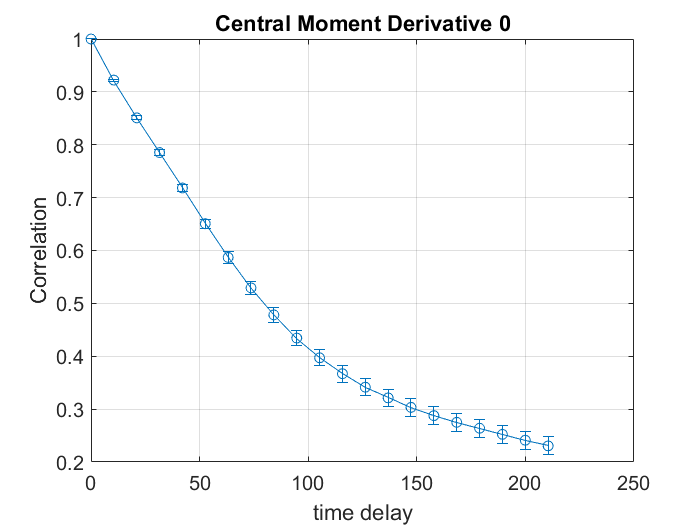

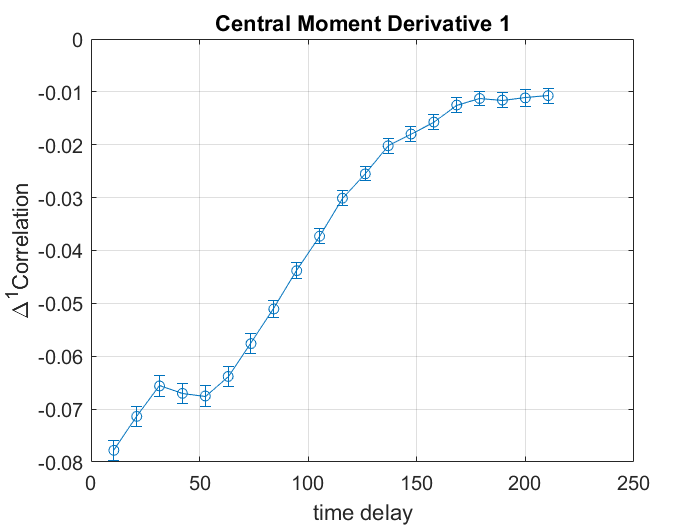

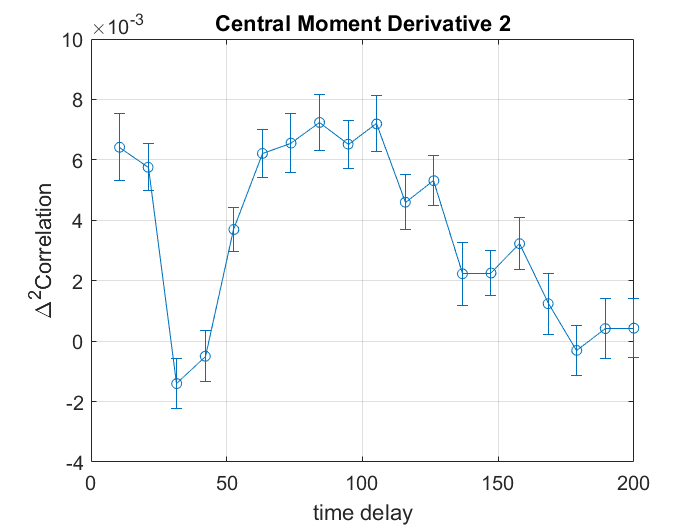

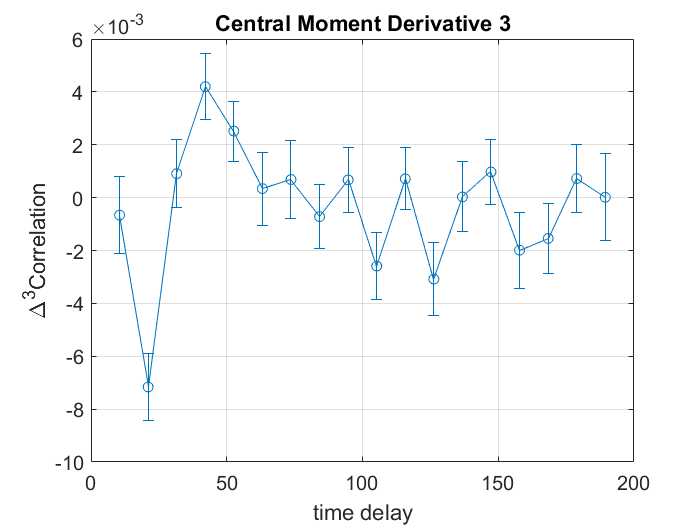


gen_auto_cor(tracesp, 0:3, true, max_delay, cut, time_res);

Prints mean fluorescence as a function of the number of time points into a trace

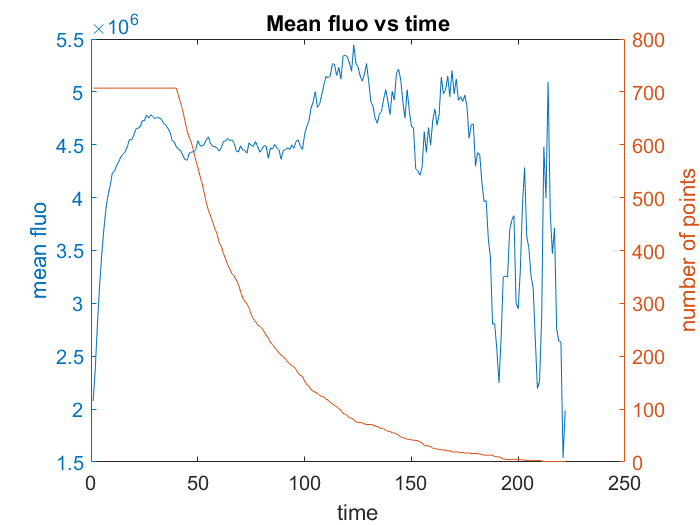

counts = zeros(1,300);
vals = zeros(1, 300);
for i = 1:length(tracesp)
    trace = tracesp{i};
    vals(1:length(trace)) = vals(1:length(trace)) + trace;
    counts(1:length(trace)) = counts(1:length(trace)) + 1;
end
ends = find(counts == 0);
vals = vals(1:ends-1) ./ counts(1:ends-1);

figure();
yyaxis left
plot(vals(1:ends-1));
ylabel('mean fluo');
yyaxis right
plot(counts(1:ends-1));
ylabel('number of points');
title('Mean fluo vs time')
xlabel('time')